# indentSine

This live script is continuation of calciumPlot.mlx and applied to the vibration stimuli with fixed force

#### Load the indenter stimulation file

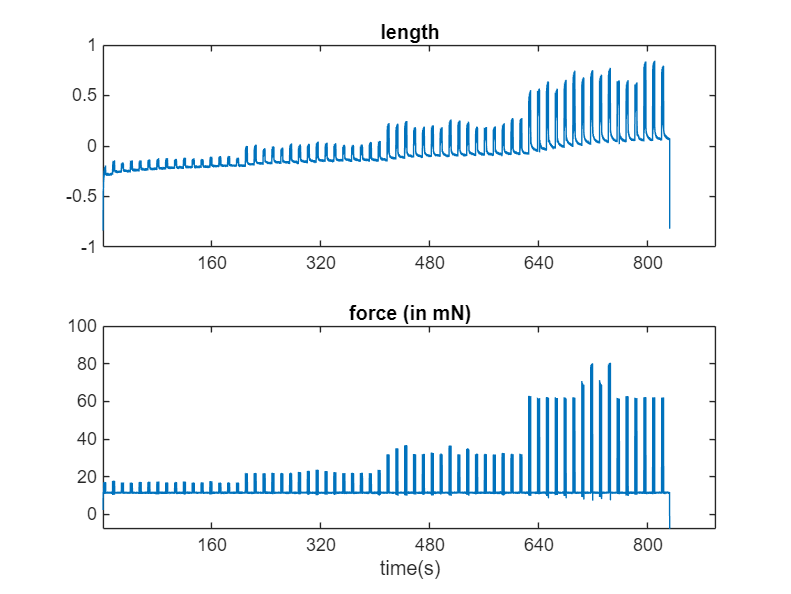

folderNameTemp = strsplit(path,filesep);
folderName = folderNameTemp{end-1};
clear folderNameTemp
close all
[filenameMat,pathMat] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Qi\stimulation\indenter\*.mat',...
    ['select an indentation file for   ', folderName]);

% [filenameMat,pathMat] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\stimulation\indenter\*.mat', ...
%     ['select an indentation file for
load([pathMat,filenameMat])
force = data(:,3);
down = 10;
figure,
tick = floor(numel(force)/Fs/5/10)*10;
% subplot(311),plot(cameraTrigger(1:10:end)),title('Trigger'),
subplot(211),plot(data(1:down:end,2)),title("length");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
subplot(212),plot(data(1:down:end,3)*50),title("force (in mN)");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
xlabel('time(s)')

% plot(force),title("force")
% pbaspect([3 1 1])
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% nUnit = ceil(length(I)/nSweep);

#### Split the indenter file

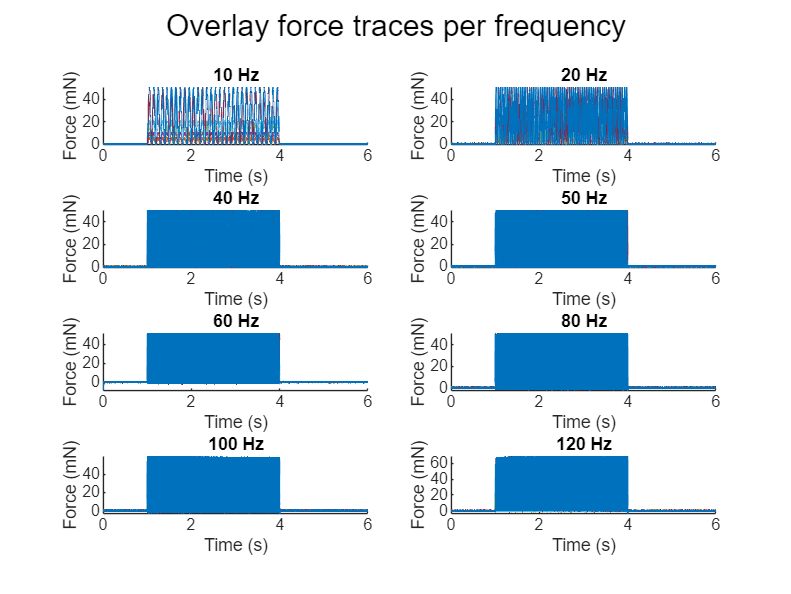

% --- prepare sizes ---
triggerDuration = sweepDuration + baseline + decayTime;
numSweeps = size(sineBoth,1);
voltageConversion = 50;
samplesPerSweep = Fs*(triggerDuration + interSweepInterval);   % matches fullForceTemp rows
activeStart = Fs*baseline + 1;
activeLen   = Fs * sweepDuration;
activeIdx   = activeStart : (activeStart + activeLen - 1);
baselineIdx = 1:(activeStart-1);
% recorded force vector (from your data). adjust column index if different
recordedForce = data(:,3);          % recorded analog force (volts)

% reshape back into matrix: rows = samplesPerSweep, cols = sweeps
recForceMat = reshape(recordedForce, samplesPerSweep, numSweeps);

Force_freq = zeros(samplesPerSweep*nRepeat*length(sineAmplitude),length(sineFrequency));

for i = 1:length(sineFrequency)
    freq_idx = find(sineBoth(:,2)== sineFrequency(i));
    force_temp = recForceMat(:,freq_idx);
    baselineMean = mean(force_temp(baselineIdx,:), 1);
    force_temp = force_temp - baselineMean;
    Force_freq(:,i) = force_temp(:);
end


rows = 4;
cols = 2;

figure(1)
t = (0:samplesPerSweep-1)/Fs;

for i = 1:length(sineFrequency)
    
    tmp = reshape(Force_freq(:,i), samplesPerSweep, []);
    
    subplot(rows, cols, i)
    hold on
    
    for k = 1:size(tmp,2)
        p = plot(t, tmp(:,k)*voltageConversion, 'LineWidth', 0.8);
        p.Color(4) = 0.2;   % transparency (lower = more transparent)
    end
    
    xlim([0 6])
    title(sprintf('%d Hz', sineFrequency(i)))
    ylabel('Force (mN)')
    xlabel('Time (s)')
end

sgtitle('Overlay force traces per frequency');


% Construct a config struct for the function
cfg = struct();
cfg.Fs = Fs;
cfg.cameraTriggerRate = cameraTriggerRate;
cfg.baseline = baseline;
cfg.sweepDuration = sweepDuration;
cfg.decayTime = decayTime;
cfg.voltageConversion = voltageConversion;
cfg.sineBoth = sineBoth;
cfg.sineFrequency = sineFrequency;
cfg.sineAmplitude = sineAmplitude;   % force levels (mN)
cfg.recForceMat = recForceMat;
clearvars time cameraTrigger data Data force tmp t recordedForce force_temp Force_freq

####  Align the indentation with response and save the figure

nCell = 1

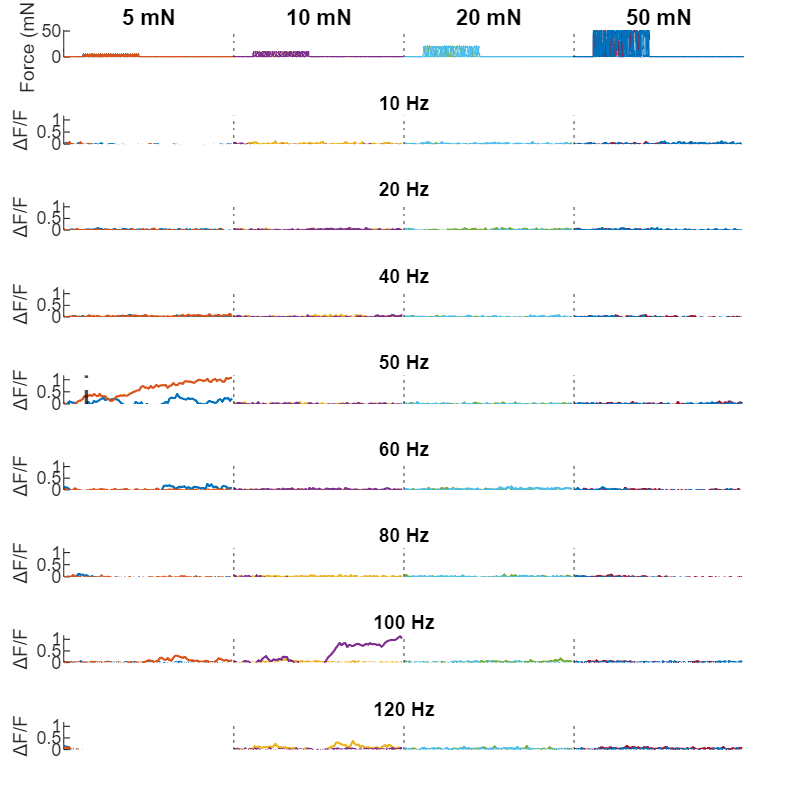

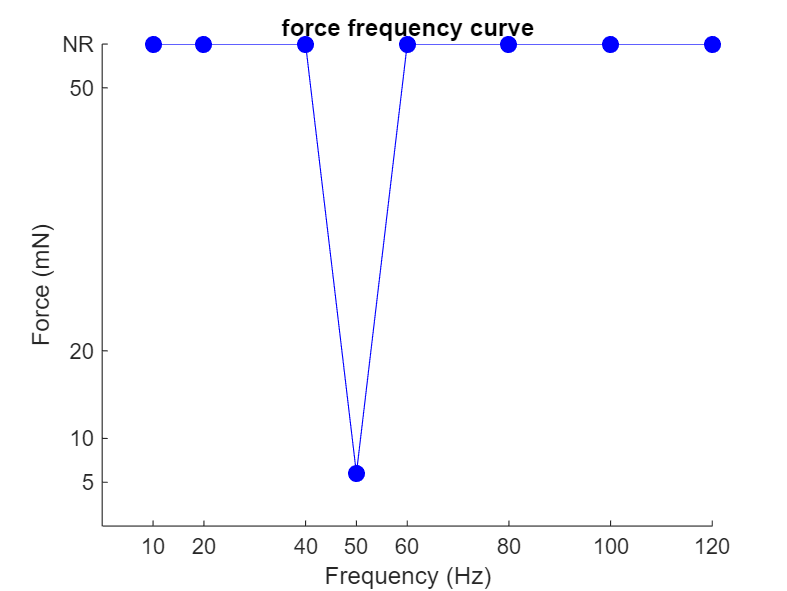

nCell = 2

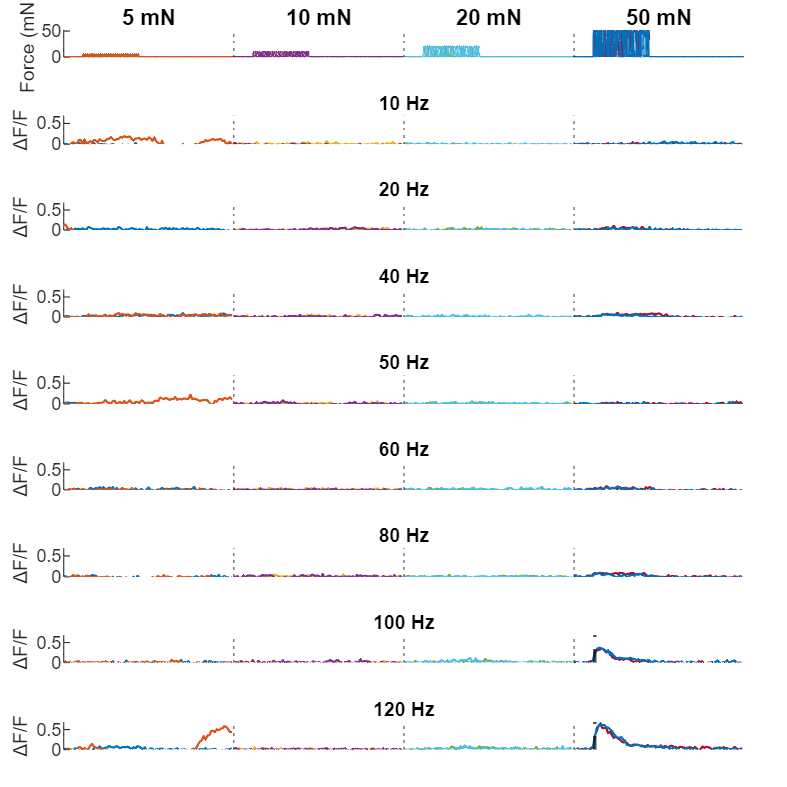

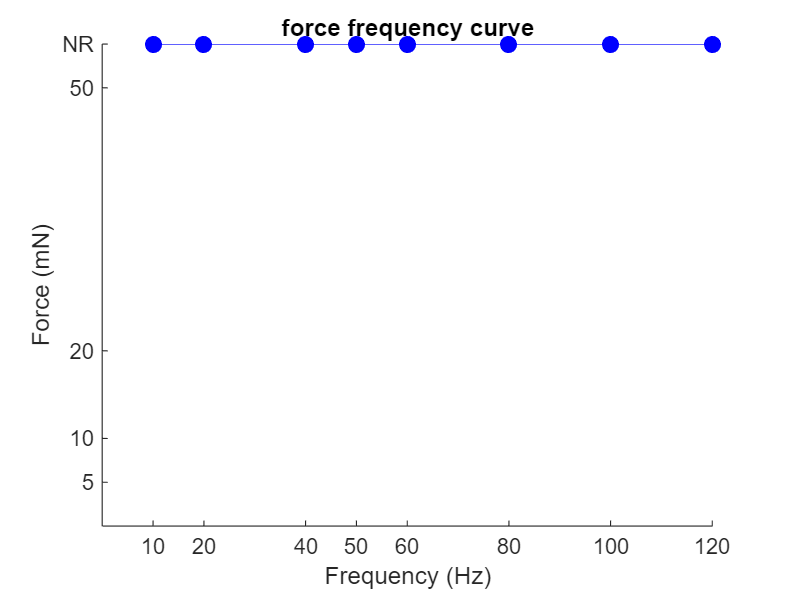

nCell = 3

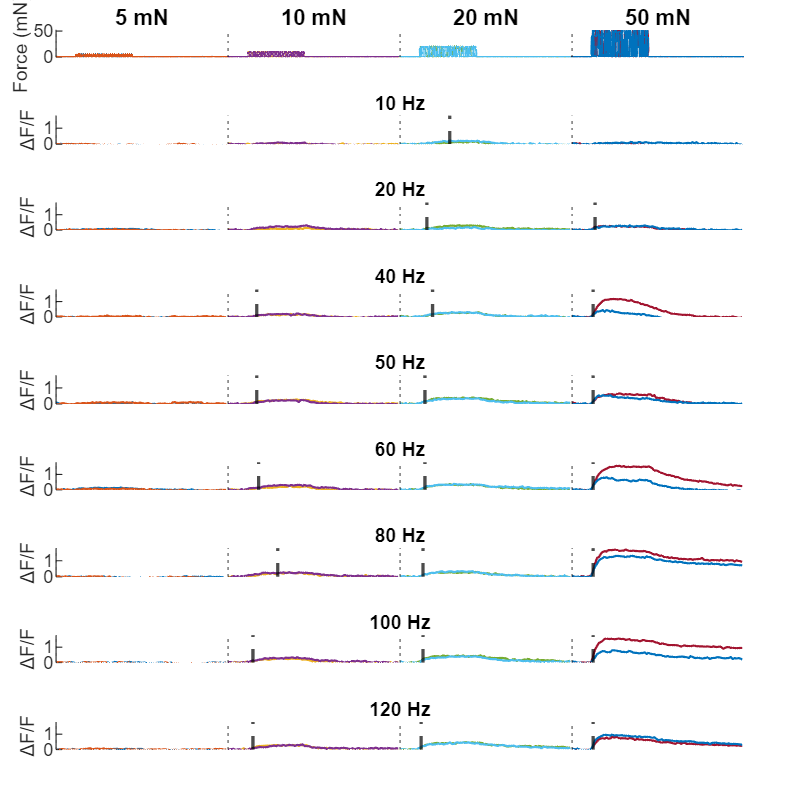

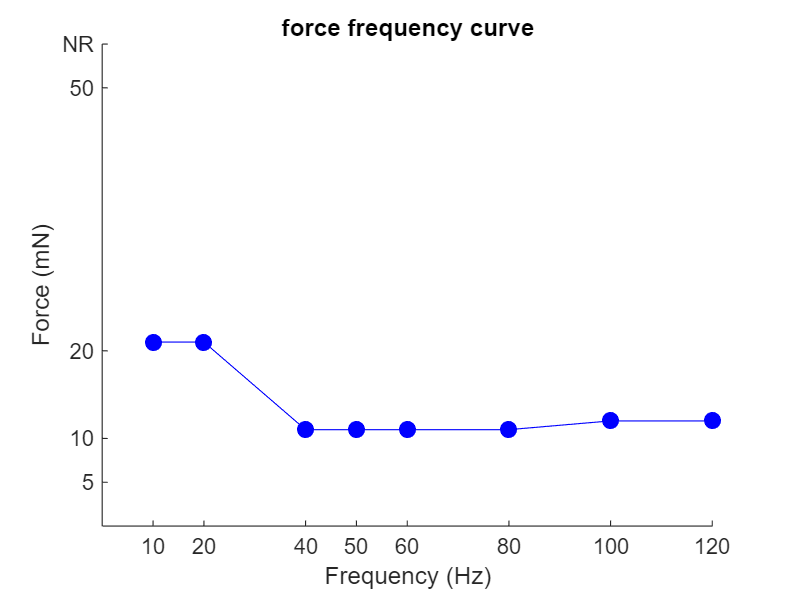

nCell = 4

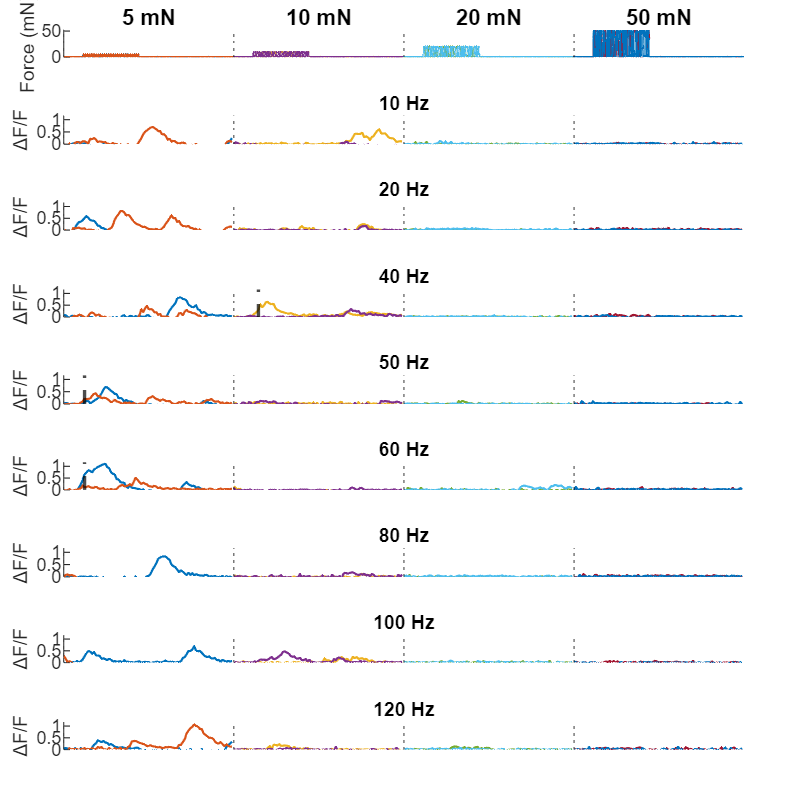

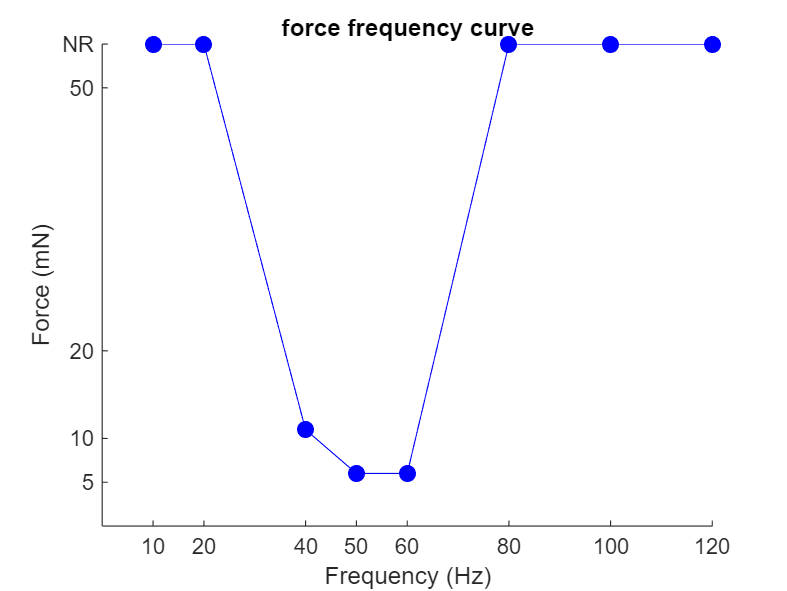

nCell = 5

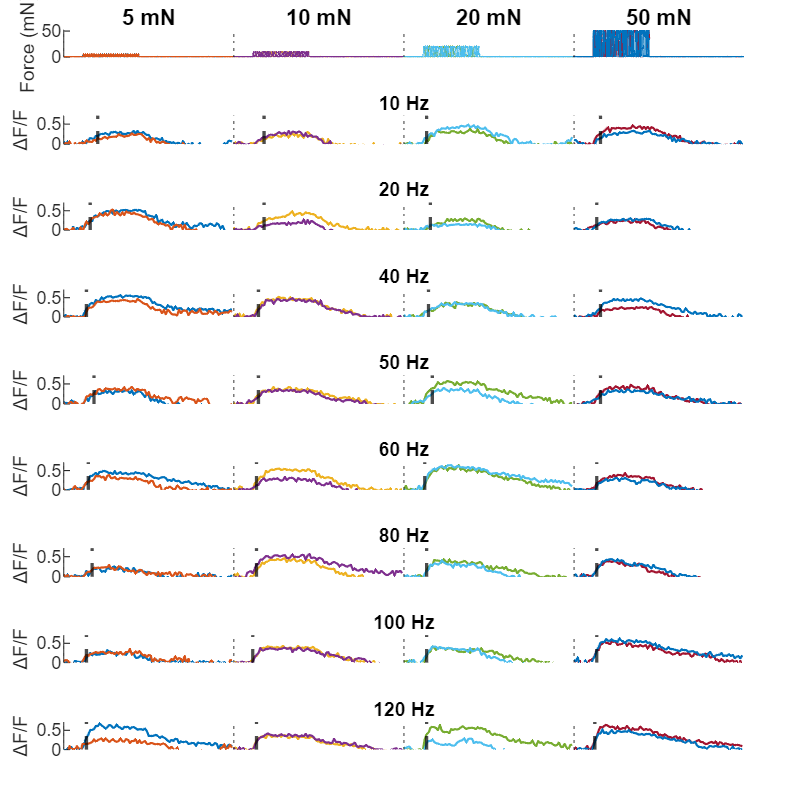

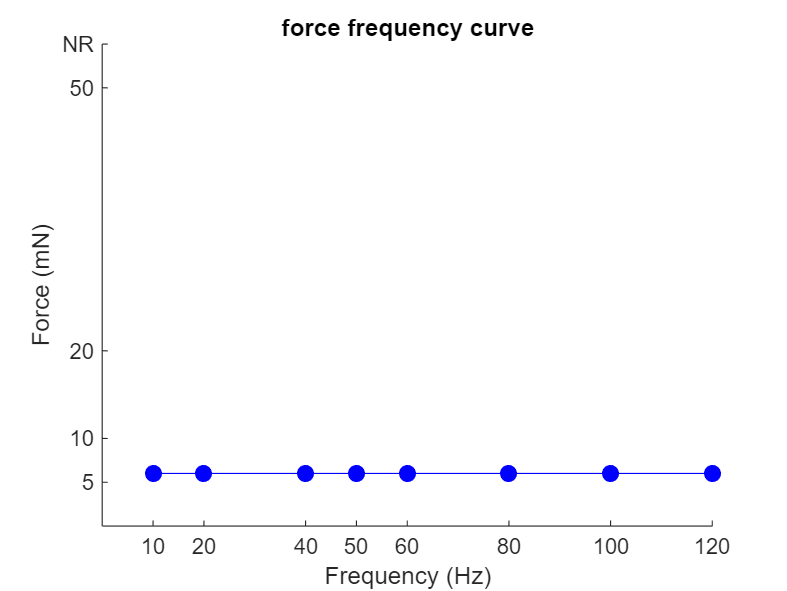

nCells = [1:size(normDeltaF,2)];
nStd = 5;
minConsec = 10;
freqTop = 10;
AllCell_freq_threshold = struct();
AllCell_AUC = struct();
vibFolder = strcat(path,filename(1:end-4)) ;
if ~exist(vibFolder, 'dir')
    mkdir(vibFolder);
end
out = regexp(vibFolder, '(?<=calcium\\)(.*?)(?=\\preprocess)', 'match', 'once');

threshName = fullfile(vibFolder, [out,'_Neuron',sprintf('%d', nCells),'_threshVibStepSum.mat']);

% Calcium timing indices
calciumBaselineIdx = 1:round(baseline * fps);

calciumActiveStart = round(fps * baseline) + 1;
calciumActiveLen   = round(fps * sweepDuration);
calciumActiveIdx   = calciumActiveStart : (calciumActiveStart + calciumActiveLen - 1);

for j = 1: numel(nCells)
    nCell = nCells(j)
    normDeltaFncell = normDeltaF(:,nCell);
    m = length(normDeltaFncell);
    nUnit = floor(m/numSweeps);
    newDeltaF = zeros(nUnit, numSweeps);
    for i = 1:numSweeps
        if i*nUnit < size(normDeltaF,1)
            newDeltaF(:, i) = normDeltaFncell((i-1) * nUnit +1 : i * nUnit) ;
        else
            newDeltaF(:, i) = [normDeltaFncell((i-1) * nUnit +1 : end); zeros(i * nUnit - size(normDeltaF,1), 1)];
        end
        % [~, newDeltaF(:, i), ~] = RobustDetrend(newDeltaF(:, i), 6, 0.975);
        newDeltaF(:,i) = newDeltaF(:,i) - mean(newDeltaF(1:baseline * fps, i)); %correct the baseline
    end
    calciumActiveIdx_use = calciumActiveIdx(calciumActiveIdx >= 1 & calciumActiveIdx <= size(newDeltaF, 1)); 
    tCalcium_auc = (calciumActiveIdx_use(:) - calciumActiveIdx_use(1)) / fps;

    Calcium_freq = zeros(size(newDeltaF,1)*nRepeat*length(sineAmplitude),length(sineFrequency));
    
    for i = 1:length(sineFrequency)
        freq_idx = find(sineBoth(:,2)== sineFrequency(i));
        calcium_temp = newDeltaF(:,freq_idx);
        Calcium_freq(:,i) = calcium_temp(:);
    end
    Cell_freq_forceThreshold = Align_forceSine_calcium(nCell, Calcium_freq,cfg,vibFolder,nStd,minConsec,freqTop);
    fieldname_cell = matlab.lang.makeValidName(sprintf('Neuron%d', nCell));
    AllCell_freq_threshold.(fieldname_cell) = Cell_freq_forceThreshold;


    aucType = 'pos';   % use 'pos' for positive AUC, or 'raw' for signed AUC

    Cell_AUC = struct();

    for a = 1:length(sineAmplitude)

        amp = sineAmplitude(a);
        ampField = matlab.lang.makeValidName(sprintf('Force_%gmN', amp));

        % One AUC value per frequency
        Cell_AUC.(ampField) = zeros(1, length(sineFrequency));

        for f = 1:length(sineFrequency)

            freq = sineFrequency(f);

            % Assumes:
            % sineBoth(:,1) = force amplitude
            % sineBoth(:,2) = sine frequency
            sweep_idx = find(sineBoth(:, 1)*voltageConversion == amp & sineBoth(:, 2) == freq);

            if isempty(sweep_idx)
                Cell_AUC.(ampField)(f) = NaN;
                continue
            end

            calciumTraces = newDeltaF(calciumActiveIdx_use, sweep_idx);

            % Signed AUC during vibration only
            auc_eachSweep_raw = trapz(tCalcium_auc, calciumTraces, 1);

            % Positive-only AUC during vibration only
            auc_eachSweep_pos = trapz(tCalcium_auc, max(calciumTraces, 0), 1);

            switch aucType
                case 'raw'
                    Cell_AUC.(ampField)(f) = mean(auc_eachSweep_raw, 'omitnan');

                case 'pos'
                    Cell_AUC.(ampField)(f) = mean(auc_eachSweep_pos, 'omitnan');
            end

        end
    end


    AllCell_AUC.(fieldname_cell) = Cell_AUC;
end


save(threshName,'AllCell_freq_threshold','AllCell_AUC');

**Filter out low quality neurons if needed**

neurons_toskip = input('Enter neuron indices to skip (e.g., [1 2 5 7]): ');
fields = fieldnames(AllCell_freq_threshold);
fields_to_remove = fields(neurons_toskip);
AllCell_freq_threshold_filtered = rmfield(AllCell_freq_threshold, fields_to_remove);
threshName_filtered = strrep(threshName, '_threshVibStepSum.mat', '_threshVibStepSum_filtered.mat');
save(threshName_filtered, 'AllCell_freq_threshold_filtered');

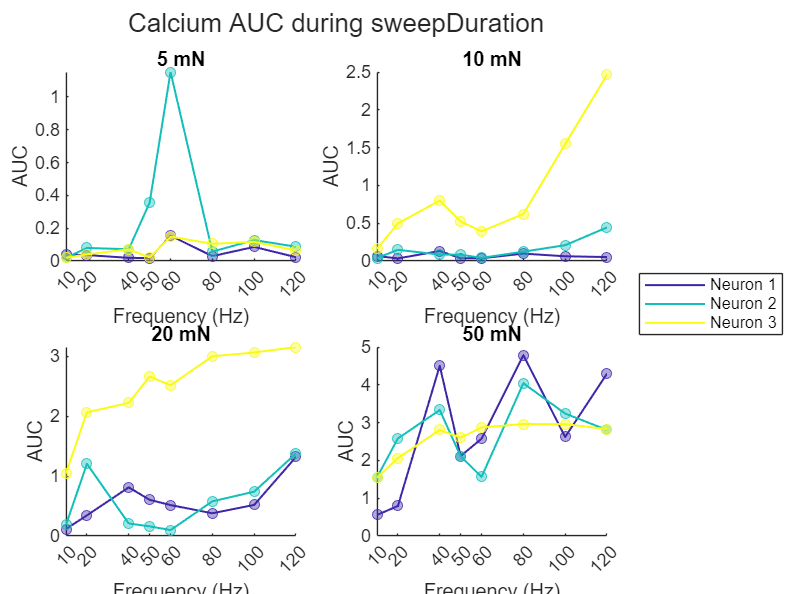

% ================================================================
% Plot AUC vs frequency
% Different forces on different subplots
% All cells on the same plot
% AUC = 0 if threshold is not reached
% ================================================================

nCells = 1:size(normDeltaF, 2);
nForces = length(sineAmplitude);
nFreqs = length(sineFrequency);

rows = ceil(sqrt(nForces));
cols = ceil(nForces / rows);
cellColors = parula(numel(nCells));


figure;
set(gcf, 'Color', 'w');

t = tiledlayout(rows, cols, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

legendHandles = gobjects(numel(nCells), 1);
legendNames = cell(numel(nCells), 1);

for a = 1:nForces

    amp = sineAmplitude(a);
    ampField = matlab.lang.makeValidName(sprintf('Force_%gmN', amp));
    nexttile;
    hold on;

    for j = 1:numel(nCells)

        nCell = nCells(j);
        cellField = matlab.lang.makeValidName(sprintf('Neuron%d', nCell));

        % Get AUC vector for this neuron and force
        aucVec = AllCell_AUC.(cellField).(ampField);

        % Get threshold vector for this neuron
        thresholdVec = AllCell_freq_threshold.(cellField);

        % Set AUC to zero if threshold is not reached
        aucVec_plot = aucVec;

        % for f = 1:nFreqs
        % 
        %     thresholdForce = thresholdVec(f);
        % 
        %     if isnan(thresholdForce) || amp < thresholdForce
        %         aucVec_plot(f) = 0;
        %     end
        % 
        % end

        h = plot(sineFrequency, aucVec_plot, '-', ...
            'LineWidth', 1, ...
            'Color', cellColors(j, :));

        scatter(sineFrequency, aucVec_plot, 25, ...
            'o', ...
            'MarkerFaceColor', cellColors(j, :), ...
            'MarkerEdgeColor', cellColors(j, :), ...
            'MarkerFaceAlpha', 0.4, ...
            'MarkerEdgeAlpha', 0.8);

        if a == 1
            legendHandles(j) = h;
            legendNames{j} = sprintf('Neuron %d', nCell);
        end

    end

    title(sprintf('%g mN', amp));
    xlabel('Frequency (Hz)');
    ylabel('AUC');
    xticks(sineFrequency);
    xlim([min(sineFrequency), max(sineFrequency)]);
    box off;

end
lgd = legend(legendHandles, legendNames, ...
    'Interpreter', 'none', ...
    'Location', 'eastoutside');

lgd.Layout.Tile = 'east';

title(t, 'Calcium AUC during sweepDuration');